# Virtual channel conceptual

We explain the virtual channel concept. 

Conventionally, to coordinate data between two color systems we find a linear transformation of one device that approximates the channels of the second device. That is, we find a linear transform from the channels in A to match each of the chanels in B.  If the B channels are outside of the space spanned by A, we  find the 'closest' channel in A to each channel in B.

The virtual channel idea asks a slightly different question. Is there a linear combination of the A channels (virtual-A) that is close to a linear combination of the B channels (vitual-B). This is a different question, because neither of the virtual channels need exist in either device. The two virtual channels are created as weighted sums of the real channels.

The virtual channel idea may be useful for exchanging common information between two devices.  The operators of device A can send the virtual channel image to the operators of device B. They can check for an exact match between the image on the virtual channel in B.

This script illustrates the idea using low (3) dimensional representations of the channel spectral responsivities.

## Device spectral sensitivities

The devices are specified with respect to 3 wavelengths so we can render the images.  So A and B are 3-vectors.

% Device A
A = [1 .2; 0 1; 0 0];
for ii=1:2
    A(:,ii) = A(:,ii)/vectorLength(A(:,ii));
end

% Device B
B = [0 0.3; 1 0; .5 .7];
for ii=1:2
    B(:,ii) = B(:,ii)/vectorLength(B(:,ii));
end

intersection = estimatorNullNull(A,B);

O = [0,0,0];
lStyle = '-'; lWidth1 = 3; lWidth2 = 3;

axLim = 1.2;
alpha = .7;

## Show the plane

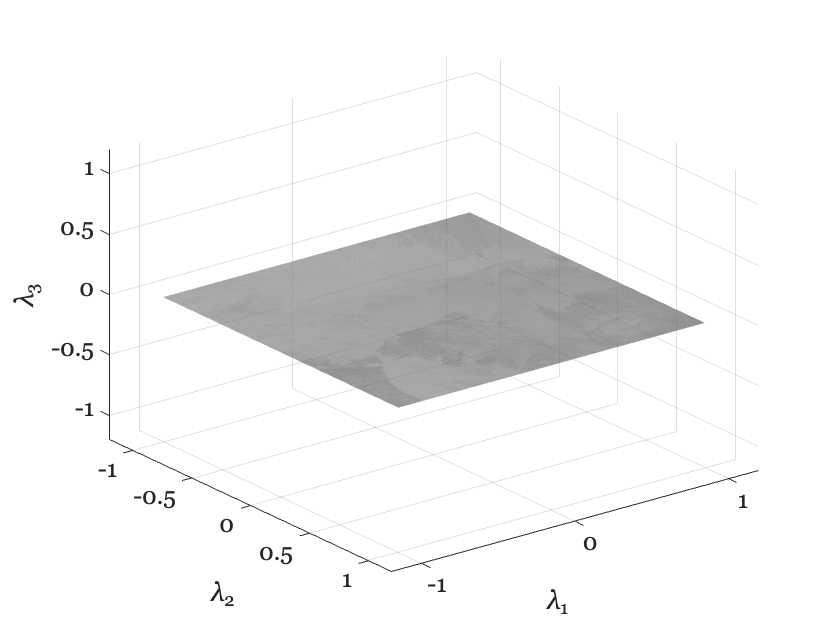

ieNewGraphWin;
set(gcf,'Position',[0.0070    0.1292    0.5727    0.7808]);

[x,y,z] = iePlaneFromVectors(A);

fname = fullfile(iefundamentalsRootPath,'fig05VirtualChannel','texture2.png');
J = imread(fname);
W1 = warp(x,y,z,J); 
W1.FaceAlpha = 0.7;
set(gca,'zlim',[-axLim axLim],'ylim',[-axLim axLim],'xlim',[-axLim axLim])
lgt1 = light("Style","Infinite","Position",[-1 1 1]);
lgt1.Position = [-10 -5 5];
lgt1.Color = [1 1 1]; fontSize = 30;
tmp = xlabel('\lambda_1','FontSize',fontSize); 
ylabel('\lambda_2','FontSize',fontSize); 
zlabel('\lambda_3','FontSize',fontSize);
set(gca,'FontSize',24);
grid on; lighting gouraud;

## Show the real channels for the first device

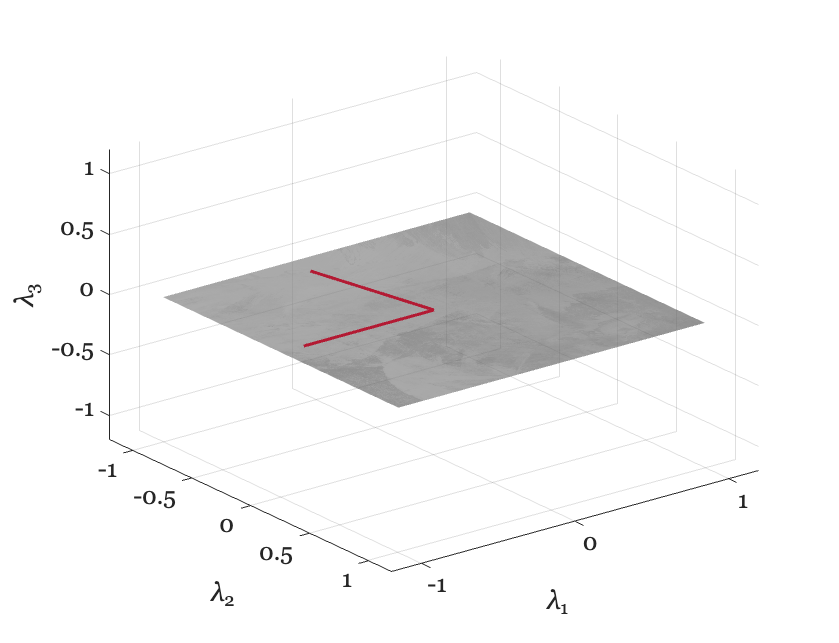

P = -0.85*A';
X = P(:, 1); Y = P(:, 2); Z = P(:, 3);
for ii=1:2
    hold on;
    %     L = quiver3(O(1), O(2), O(3), X(ii), Y(ii), Z(ii));
    deviceA(ii) = line([O(1),X(ii)],[O(2),Y(ii)],[O(3), Z(ii)]);
    deviceA(ii).LineWidth = lWidth2;
    deviceA(ii).Color = [0.7 0.1 0.2];
    deviceA(ii).LineStyle = lStyle;
end
grid on

## Show the channels for the second device

P = B';
X = P(:, 1); Y = P(:, 2); Z = P(:, 3);

for ii=1:2
    hold on;
    deviceB(ii)= line([O(1),X(ii)],[O(2),Y(ii)],[O(3), Z(ii)]); %#ok<*SAGROW>
    deviceB(ii).LineWidth = lWidth2;
    deviceB(ii).Color = [0 0.3 0.8];
    deviceB(ii).LineStyle = lStyle;
end
 
axis equal; 
set(gca,'zlim',[-axLim axLim],'ylim',[-axLim axLim],'xlim',[-axLim axLim])

view(-33,12);


## The possible channels from device B

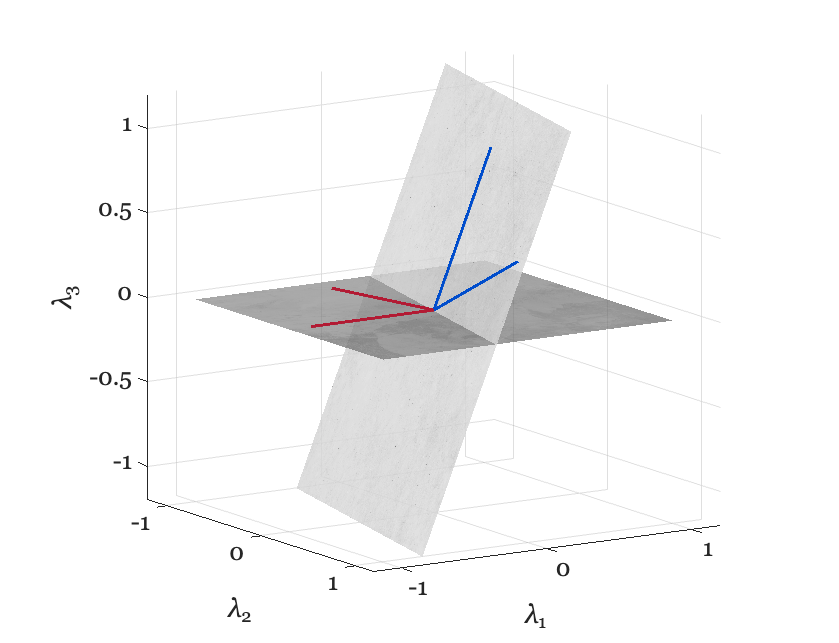

[x,y,z] = iePlaneFromVectors(B);

fname = fullfile(iefundamentalsRootPath,'fig05VirtualChannel','texture1.png');
I = imread(fname);
W = warp(x,y,z,I); W.FaceAlpha = .8;
view(-33,12);

## Show the intersection, reachable by both cameras

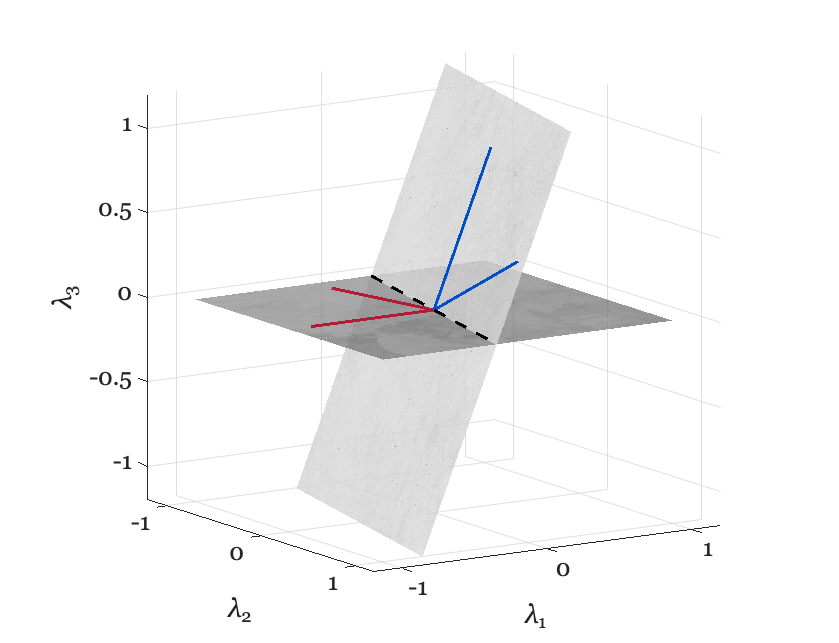

INT = line([-intersection(1),intersection(1)],[ -intersection(2),intersection(2)], [ -intersection(3), intersection(3)]);
INT.Color = 'k';
INT.LineWidth = lWidth1;
INT.LineStyle = '--';
fname = fullfile(iefundamentalsRootPath,'fig05VirtualChannel','virtualB.jpg');

deviceA(1).LineWidth = lWidth2; deviceA(2).LineWidth = lWidth2;
deviceB(1).LineWidth = lWidth2; deviceB(2).LineWidth = lWidth2;

view(-33,12);